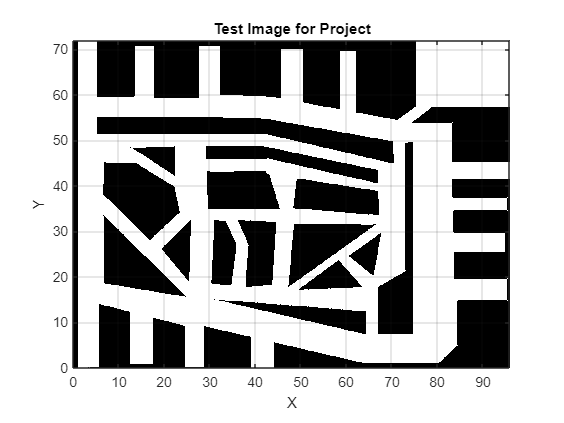

carType = 'Nuro'

34.3844 km traveled
Total emissions from simulation (kilograms carbon): 24884.9457      34531.0696      5421.18601               0


carType = 'RAM'

51.3952 km traveled
Total emissions from RAM simulation (kilograms carbon): 32.8453      28.8167      52.3322       37.736      36.2906            0


carType = 'Nuro'

25.4927 km traveled
Total emissions from simulation (kilograms carbon): 16658.1711      15983.8597      15428.3613               0


carType = 'RAM'

48.0215 km traveled
Total emissions from RAM simulation (kilograms carbon): 49.6865      61.7108      13.5634      35.9845      14.7335            0


carType = 'Nuro'

33.6482 km traveled
Total emissions from simulation (kilograms carbon): 23749.3782      11655.4854      28044.0372               0


carType = 'RAM'

42.8607 km traveled
Total emissions from RAM simulation (kilograms carbon): 3.77905      58.6062      40.1384      23.5704      30.7048            0


carType = 'Nuro'

19.3057 km traveled
Total emissions from simulation (kilograms carbon): 15896.9777      10705.1149      9801.87489               0


carType = 'RAM'

46.0338 km traveled
Total emissions from RAM simulation (kilograms carbon): 18.1337      42.5594      14.9163      46.3193      46.4782            0


carType = 'Nuro'

26.2247 km traveled
Total emissions from simulation (kilograms carbon): 23984.2459      23136.6466      2329.88997               0


carType = 'RAM'

56.4647 km traveled
Total emissions from RAM simulation (kilograms carbon): 53.3672      13.9898       41.077      49.1418      48.9909            0


carType = 'Nuro'

14.0427 km traveled
Total emissions from simulation (kilograms carbon): 13197.6238      5782.83148      7499.27748               0


carType = 'RAM'

58.1598 km traveled
Total emissions from RAM simulation (kilograms carbon): 51.0448      37.1612      28.7852       33.939      61.8375            0


carType = 'Nuro'

Error using distance
Expected state1 to be nonempty.

Error in nav.internal.validation.validateStateMatrix (line 11)
    validateattributes(state, {'double'}, {'nonempty', 'size', [numRows numStateVariables]}, ...

Error in stateSpaceDubins/distance (line 95

%% RBE 501: Path Planning Nuro Project
% Sean Tseng, Debbie G, Lucas Vanslette
%% Initialize Occupancy Map
% This section loads the road map that the robot will be navigating in this 
% project. The first step is to binarize the road map imagine. Road map is still 
% in progress, replace the name in 'imread' to read in a different image for path 
% planning.
% 
% Dubins explanation: <https://demonstrations.wolfram.com/IsochronsForADubinsCar/ 
% https://demonstrations.wolfram.com/IsochronsForADubinsCar/>

clear
clc
J = rgb2gray(imread('City map.png'));
% change so that all pixels less than 240 are all now 0 (all black)
%J(J < 240) = 0;
%J(J >= 240) = 255;

J(J > 50) = 255;


%J = J(:,:,1);
resize_fac =10;
map = binaryOccupancyMap(~J,resize_fac);
show(map)
title('Test Image for Project')
xlabel('X')
ylabel('Y')
grid on
hold on
%% Initialize Simulation Parameters
% Update state space bounds to be the same as map limits, which were generated 
% earlier with the binaryOccupancyMap method. Also, create a Dubins model of the 
% vehicle with bounds imported from the occupancy map.

bounds = [map.XWorldLimits; map.YWorldLimits; [-pi pi]];
ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.05;
%% 
% Create a state validator using the created state space and based on the occupancy 
% map created from the png image.

sv = validatorOccupancyMap(ss);
sv.Map = map;
%% 
% Set validation distance for the simulation.

sv.ValidationDistance = 0.02;
%% 
% Now the planner can be created with a modifiable maximum distance between 
% nodes of the tree.
Maxdistance = 0.4;
%% 
% Establish start and goal states. If start and/or goal position are impossible, 
% then system throws error. 

num_stops_nuro = 3;
num_stops_ram = 5;
%% 
% Enter the weight of the groceries, in pounds

% average household grocery order (assumes the same for each, assumes waypoint order size is smaller than max capacity)
order_size = 5;
%% 
% Determine which car will be simulated

% added car type to determine waypoints
carType = "Nuro";
nuroCapacity = 60;
ramCapacity = 1000;


%% 
% Calculate the random waypoints that the car will traverse

plotting = 0;   % 0 = false, 1 = true

% calculate how many times we want to run our simulation
num_sims = 20;

for i=1:num_sims
    nuroWaypoints = calculate_waypoints(map, num_stops_nuro, nuroCapacity, order_size, plotting);
    ramWaypoints = calculate_waypoints(map, num_stops_ram, ramCapacity, order_size, plotting);
    hold off
    %% 
    % Determine which path planning algorithm will be used for simulation
    algorithm = 3;

    %% 
    % *Start simulation*
    
    % added function that runs below simulation X times
    carType = 'Nuro'
    simulation(map, algorithm, nuroWaypoints, ss, sv, Maxdistance,carType, plotting);
    carType = 'RAM'
    simulation(map, algorithm, ramWaypoints, ss, sv, Maxdistance,carType, plotting);
end



%% 
% *Function calculate_waypoints: given car, calculate all places that the car 
% will stop on its route*


function waypoints = calculate_waypoints(map, num_deliveries, carCapacity, order_size, plotting)
    % waypoints = [  x1     x2   ...
    %                y1     y2   ...
    %              theta1 theta2 ... ]
    % % % test case
    % waypoints = [91  84 60;   %x
    %              44  20 24;   %y
    %              4.5 1  1 ; ] %theta

    %
    % for each waypoint
    for i=1:num_deliveries
        % generate random orientation
        rand_theta = -pi + (2*pi)*rand;
        % determine if random coordinate is valid
        while 1
            rand_x = map.XWorldLimits(2)*rand;
            rand_y = map.YWorldLimits(2)*rand;
            if ~checkOccupancy(map, [rand_x rand_y])
                break
            end
        end
        % save as a new waypoint
        waypoints(:,i) = [rand_x; rand_y; rand_theta;];
    end

    % add initial waypoint to the end to return to store
    waypoints(:,end+1) = waypoints(:,1);

    % added number of times to refill, which is the minimum number of times Nuro would have
    %   to go back to the start and refill its capacity for groceries
    num_stops_until_refill = ceil(carCapacity / order_size);


    % for every x stops, you need to refill at the store
    if num_stops_until_refill < num_deliveries
        for i=1:num_stops_until_refill:num_deliveries
            % add store waypoint to refill car
            waypoints = [waypoints(:,1:i*num_stops_until_refill) waypoints(:,1) waypoints(:,i*num_stops_until_refill+1:end)];
        end
    end

    if plotting
        % plot waypoints in BIG lettering
        % scatter(x,y,sz,symbol,'filled')
        scatter(waypoints(1, 2:end), waypoints(2, 2:end), 140, 'filled');
        % plot the first waypoint (the store) in a different way
        scatter(waypoints(1,1), waypoints(2,1), 140, 'r', 'filled');
        legend('Goal Locations', 'Store', 'Location', 'northoutside');
    end
end
%% 
% 

function simulation(map, algorithm, waypoints, ss, sv, Maxdistance,carType,plotting)
%% User Defined Path Planning
% Choose what planning algorithm to use, options include RRT, RRT*, Bidirectional 
% RRT, Hybrid A*, A* from the drop down menu. The A* algorithm only accepts a 
% 2x1 vector instead of a 3x1 vector like the other algorithms.

choose = algorithm;
    switch choose
        case 1
            planner = plannerRRT(ss,sv,MaxConnectionDistance=Maxdistance);
        case 2
            planner = plannerRRTStar(ss,sv,MaxConnectionDistance=Maxdistance);
        case 3
            planner = plannerBiRRT(ss,sv,MaxConnectionDistance=Maxdistance);
    end
planner.MaxIterations = 1000000;
%% Plotting Results
% If the user wants to select the option to see the whole tree expansion or 
% not in the dropdown below.

plot_choose = false;
%% 
% Enter the number of waypoints for the simulation

% changed to add waypoints based on number of inputted waypoints
wayP = length(waypoints);
distance = zeros(1,wayP);
% RRT and RRT* Plot
% This else condition is for the RRT and RRT* algorithms, the plan function 
% creates plan based on the  arguments inputed into the function. Most of the 
% path planning algorithms are plotted the same way, but the RRT algorithms are 
% more complex than that of the A* derivatives.
% 
% All path planning algorithms must create a plan using the plan function, which 
% takes the planner object created in the *'User Defined Path Planning Section'*. 
% This returns a navPath object and a data structure called 'solnInfo' used for 
% plotting.

if choose == 1 || choose == 2
%% 
% The results are then collected and presented in graphical form. For RRT based 
% algorithms, the tree must iterated over and each node fed into the plot graph 
% from the data structure object called solnInfo. Then the path is drawn using 
% data from the navPath object.
if plotting
    show(map)
        % Must always change the title in this section here
    string_title = append("RRT* Planned Path",carType);
    title(string_title)
    xlabel('X')
    ylabel('Y')
    grid on
    hold on
end
%% 
% The for loop is for iterating through the entire set of waypoints that the 
% user has given.

for i =1:wayP-1
    start = waypoints(:,i)';
    goal = waypoints(:,i+1)';

    [pthObj,~] = plan(planner,start,goal);
    path=plan(planner,start,goal);
%% 
% The path length is found using the function pathLength, this will be used 
% to determine the emission of the vehicle's path.

    distance(1,i)=pathLength(path);
%% 
% If the user wants to plot the whole tree expansion, the if condition will 
% read true and the code to plot the expansion will execute, otherwise only the 
% planned path will be plotted.

    % if plot_choose ==true
    %     % Tree expansion
    %     plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-')
    % end

    % Draw path for this waypoint path
    if plotting
        plot(pthObj.States(:,1),pthObj.States(:,2),'-','LineWidth',2)
        legend_plots{i} = sprintf('Waypoint %i to %i', i, i+1);
    end
end
%% 
% List the final coordinates of the robot.

% disp(pthObj.States(end,1))
% disp(pthObj.States(end,2))
% disp(pthObj.States(end,3))
% Bidirectional RRT Plot
% <https://ieeexplore.ieee.org/document/9638379 https://ieeexplore.ieee.org/document/9638379>
% 
% This section is for plotting the results from Bidirectional RRT algorithm. 
% The code is generally the same as that of RRT and RRT*, but there are 2 tree 
% expansions, one for the forward tree, and one for the backwards tree. When these 
% two trees meet each other, the backward tree will act as a heuristic to guide 
% the forward tree to continuously grow toward the goal state, where the algorithm 
% switches to unidirectional search mode. 

elseif choose == 3
%% 
% There is also an option here to enable connect heuristic for the planner object.
if plotting
    show(map)
    string_title = append("Bi-RRT Planned Path ",carType);
    title(string_title)
    xlabel('X')
    ylabel('Y')
    grid on
    hold on
end

planner.EnableConnectHeuristic = false;
% for each waypoint
for i =1:wayP-1
    start = waypoints(:,i)';
    goal = waypoints(:,i+1)';

    [pthObj,~] = plan(planner,start,goal);
    path =  plan(planner,start,goal);
    distance(1,i)=pathLength(path);
    
%% 
% Now the tree expansion can be drawn, if the user selected to show all tree 
% expansions, the if condition will be read as true, otherwise only the optimized 
% path will be drawn.

    % Start tree expansion
    % if plot_choose == true
    % plot(solnInfo.StartTreeData(:,1),solnInfo.StartTreeData(:,2), ...
    %     '.-','color','b')
    % % Goal tree expansion
    % plot(solnInfo.GoalTreeData(:,1),solnInfo.GoalTreeData(:,2), ...
    %     '.-','color','g')
    % end

    % Draw path
    if plotting
        plot(pthObj.States(:,1),pthObj.States(:,2),'-','LineWidth',2);
        legend_plots{i} = sprintf('Waypoint %i to %i', i, i+1);
    end
end
%% 
% end planning algorithm

end
%% 
% 

if plotting
    % plot waypoints in BIG lettering
    % scatter(x,y,sz,symbol,'filled')
    scatter(waypoints(1, 2:end), waypoints(2, 2:end), 140, 'filled');
    % plot the first waypoint (the store) in a different way
    scatter(waypoints(1,1), waypoints(2,1), 140, 'r', 'filled');
    legend_plots{end+1} = 'Goal Locations';
    legend_plots{end+1} = 'Store';
    legend(legend_plots, 'Location', 'northoutside');
    hold off
end
%% Calculating Vehicle Emissions
% Nuro Emissions Calculations

if carType == "Nuro"
%% 
% This section will be for calculating the emission of the vehicle. The Nuro 
% autonomous vehicle has the following stats:
% 
% source: <https://www.sciencedirect.com/science/article/pii/S1361920920306301?casa_token=4RF5gYc7sf0AAAAA:7oqllUDzDqQI1obliIZy6W-ZWc2Pb8iyKLOGftvfJhuyTarsgXleM2OWCz4InrdWO_vEl0Nyhw 
% https://www.sciencedirect.com/science/article/pii/S1361920920306301?casa_token=4RF5gYc7sf0AAAAA:7oqllUDzDqQI1obliIZy6W-ZWc2Pb8iyKLOGftvfJhuyTarsgXleM2OWCz4InrdWO_vEl0Nyhw>
%% 
% * Payload = 110 kg
% * range = 16.1 km
% * Energy consumption = 139.6 wh/km
%% 
% Factoring in energy production for the state of MA:
% 
% <https://www.eia.gov/state/?sid=MA#tabs-4 https://www.eia.gov/state/?sid=MA#tabs-4>
% 
% Dec 2022:
%% 
% * Petroleum-Fired = 8.9%, 180,000 MWh
% * Natural Gas Fired = 73.9%  1,492,000 MWh
% * Coal Fired = 0.0%
% * Nuclear = 0%
% * Renewables = 15% 303,000 MWh
%% 
% <https://www.forestresearch.gov.uk/tools-and-resources/fthr/biomass-energy-resources/reference-biomass/facts-figures/carbon-emissions-of-different-fuels/ 
% https://www.forestresearch.gov.uk/tools-and-resources/fthr/biomass-energy-resources/reference-biomass/facts-figures/carbon-emissions-of-different-fuels/>
% 
% Assessing and averaging total carbon emission of MA. Natural gas is 202 kg/Mwh, 
% Petroleum is 260 kg/MWh. Therefore MA carbon emission stands at 348,184,000 
% kg CO_2 in December.
% 
% 

%Find weighted average 
p_carbon = 180000;
gas_carbon = 1492000;
carbon_energy = p_carbon + gas_carbon;
p_weight = p_carbon/carbon_energy;
gas_weight = gas_carbon/carbon_energy;
%% 
% This weighted average calculates the actual MA carbon emission as kg CO2 per 
% MWh of carbon based fuel burned. 

%Employ formula
avg_MA_carbon= p_weight*p_carbon+gas_weight*gas_carbon;
%% 
% Now using information from Nuro, convert the kg/MWh of the MA electric grid 
% to kg/wh and then multiply that by the Nuro's wh/km to get the average kg CO2 
% per km of the Nuro vehicle, which is the following:

nuro_carbon = avg_MA_carbon/1000000*139.6;
%% 
% Now the total distance traveled will be multiplied by Nuro's carbon footprint 
% per kilometer to yield the total emissions for the trip.

%calculating emissions (just placeholder sample) change the the calculation
%to actual emissions data
total_distance = sum(distance,'all')*.1; %to get km from hectometer --> need to change  
disp(append(num2str(total_distance),' km traveled'));
emiss = distance*nuro_carbon;
disp(append('Total emissions from simulation (kilograms carbon): ',num2str(emiss)));
%% Dodge RAM Emissions
% This is section is for calculating the emissions from the dodge ram vehicle 
% if it is chosen as the vehicle
% 
% <https://www.fueleconomy.gov/feg/bymake/Ram2021.shtml https://www.fueleconomy.gov/feg/bymake/Ram2021.shtml>
% 
% 2021 RAM Promaster City has 24 MPG, tank size 16.1 gallons, 1760 pounds payload, 
% about 800 kg 
% 
% <https://www.eia.gov/environment/emissions/co2_vol_mass.php https://www.eia.gov/environment/emissions/co2_vol_mass.php>
% 
% Gasoline emits about 8.78 kg CO2 per gallon

else
   mpg = 24;
   tank_size = 16.1; %gallons
   RAM_tank_emiss=tank_size*8.78; %emissions per full tank
   range = tank_size*mpg; %miles per full tank
   RAM_carbon_mile = RAM_tank_emiss/range;
   total_distance = sum(distance,'all')*.1; %to get km from hectometer --> need to change  
   disp(append(num2str(total_distance),' km traveled'))
   emiss = distance*RAM_carbon_mile;
   disp(append('Total emissions from RAM simulation (kilograms carbon): ',num2str(emiss)));
end


end